#### Setting the Seed 

rng(5);

#### The Value of  N is choosen from the List Below 

N_values = [5,10,20,40,60,80,100,500,1000,10000];
sz = length(N_values);

#### Given Data is 

lambda_t = 5;

%The parameters of the prior function
beta = 1;
alpha = 5.5;

#### Matrices to store the boxplots

    ML_lambda_dev = zeros(100,sz);
    MAP_lambda_dev = zeros(100,sz);

#### Making the Draws for (M = 100) number of times 

for j=1:sz
    for i=1:100
         %Generating N points from the Uniform Distribution
         x_vals = rand(N_values(j),1);

         %Transforming the points generated
         y_vals = log(x_vals)/(-lambda_t);

####                    ML-ESTIMATE 

         % The ML_estimate of the PDF of y (exponential) Comes
         % as 1/mean_of_observations
         ML_lambda = N_values(j)/sum(y_vals);
         ML_lambda_dev(i,j) = abs(ML_lambda - lambda_t)/ lambda_t;

####                    POSTERIOR-MEAN-ESTIMATE 

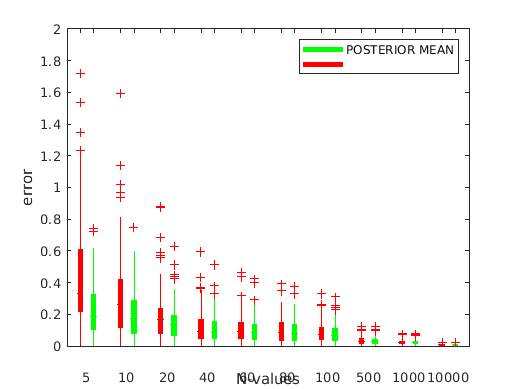

         % The New parameters for the posterior distribution
         Beta = beta + sum(y_vals);
         Alpha = alpha + N_values(j);
         MAP_lambda = Alpha/Beta;
         MAP_lambda_dev(i,j) = abs(MAP_lambda - lambda_t)/lambda_t;
    end
end
figure
labels = {' ',' '};
grpLabels = {'5','10','20','40','60','80','100','500','1000','10000'};
x = {ML_lambda_dev,MAP_lambda_dev};
boxplotGroup(x,'Colors', 'rg','BoxStyle', 'filled','primaryLabels',labels,'SecondaryLabels',grpLabels)
xlabel("N-values");
ylabel("error") ;
ylim([0 2]);
h = findall(gca,'Tag','Box');
legend([h(1:1),h(11:11)],{'POSTERIOR MEAN', 'MLE'});